% 06_hierarchical_clustering.m
% Data: customerSegmentationLab.xlsx

clear; clc; close all;

data = readtable('customerSegmentationLab.xlsx', 'ReadRowNames', true);
disp(data);

                   Age    AnnualIncome    SpendingScore    OnlineVisits    AvgPurchaseValue    DiscountSensitivity
                   ___    ____________    _____________    ____________    ________________    ___________________

    Customer 1     23          28              82               24                38                   79         
    Customer 2     25          32              77               21                42                   74         
    Customer 3     22          26              88               26                35                   81         
    Customer 4     27          35              80               19                46                   69         
    Customer 5     2


x = data{:,:};

% Standardize
sta = zscore(x);
disp('Standardized data (first 5 rows):'); disp(sta(1:5,:));

Standardized data (first 5 rows):
   -1.2629   -1.2149    1.2037    1.6129   -0.9282    0.8961
   -1.1067   -1.0084    0.9604    1.1370   -0.7787    0.6598
   -1.3410   -1.3181    1.4957    1.9302   -1.0404    0.9905
   -0.9504   -0.8535    1.1064    0.8197   -0.6292    0.4236
   -1.1848   -1.1116    1.3497    1.2956   -0.8535    0.8016



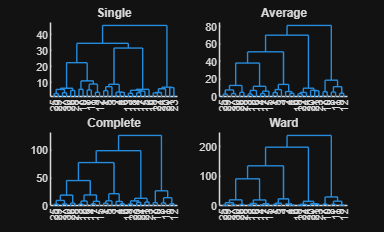


% Linkage with Ward's method
tree = linkage(x, 'ward', 'euclidean');

% Different linkages
single_link = linkage(x, 'single');
average_link = linkage(x, 'average');
complete_link = linkage(x, 'complete');
ward_link = linkage(x, 'ward');

% Dendrograms
figure;
subplot(2,2,1); dendrogram(single_link); title('Single');
subplot(2,2,2); dendrogram(average_link); title('Average');
subplot(2,2,3); dendrogram(complete_link); title('Complete');
subplot(2,2,4); dendrogram(ward_link); title('Ward');

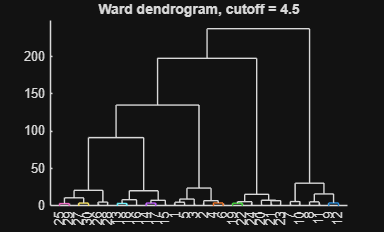


% Ward with color threshold
figure;
cutoff = 4.5;
dendrogram(ward_link, 0, 'ColorThreshold', cutoff);
title(['Ward dendrogram, cutoff = ', num2str(cutoff)]);

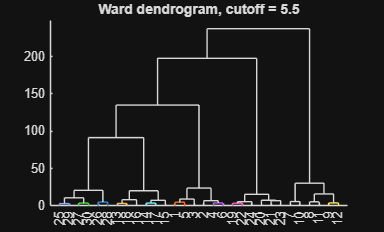

id1 = cluster(ward_link, 'criterion', 'distance', 'cutoff', cutoff);

cutoff2 = 5.5;
figure;
dendrogram(ward_link, 0, 'ColorThreshold', cutoff2);
title(['Ward dendrogram, cutoff = ', num2str(cutoff2)]);

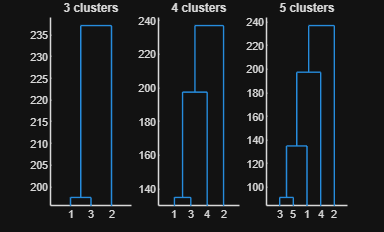

id2 = cluster(ward_link, 'criterion', 'distance', 'cutoff', cutoff2);

% Compare 3,4,5 clusters
figure;
subplot(1,3,1); dendrogram(ward_link, 3); title('3 clusters');
subplot(1,3,2); dendrogram(ward_link, 4); title('4 clusters');
subplot(1,3,3); dendrogram(ward_link, 5); title('5 clusters');